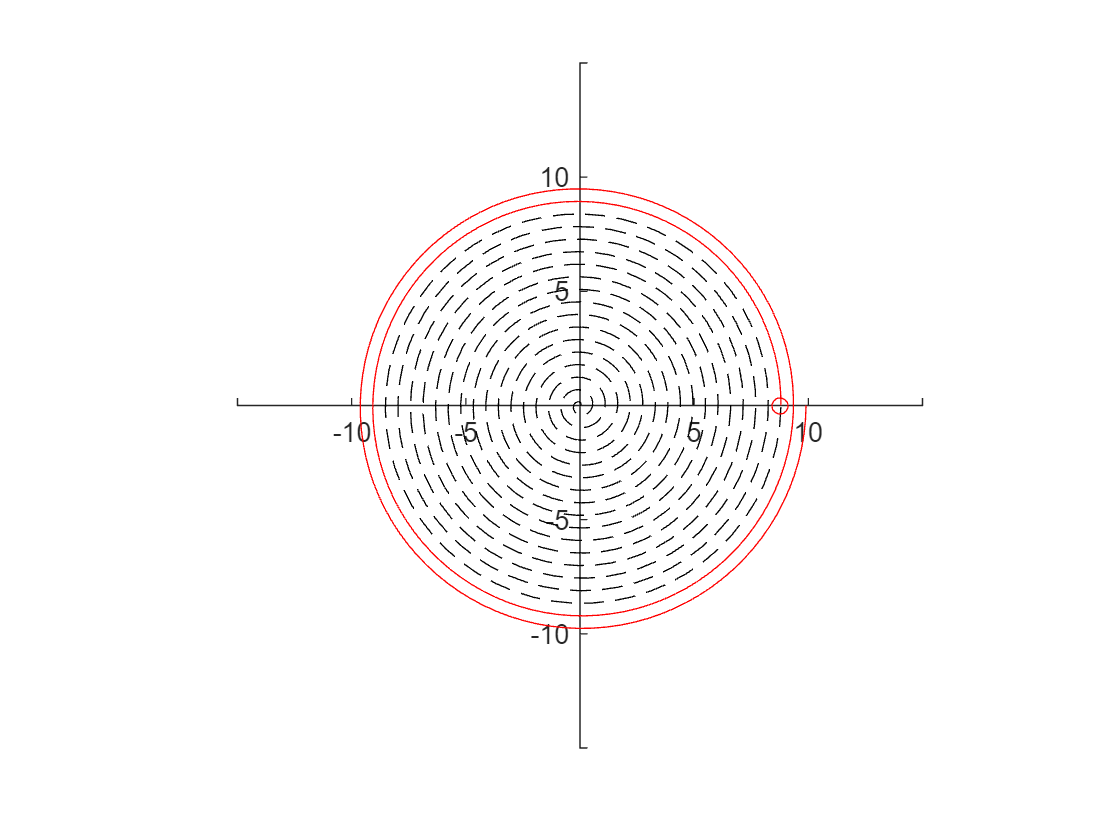

figure;
hold on;
thetas1 = linspace(0,32*pi,1000);
x1 = 0.275/pi * thetas1 .* cos(thetas1);
y1 = 0.275/pi * thetas1 .* sin(thetas1);

thetas2 = linspace(32*pi, 36*pi ,200);
x2 = 0.275/pi * thetas2 .* cos(thetas2);
y2 = 0.275/pi * thetas2 .* sin(thetas2);

plot(x1, y1, '--k');
plot(x2, y2, '-r');
plot(8.8,0,'or')
axis equal;
xlim([-15,15]);
ylim([-15,15]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

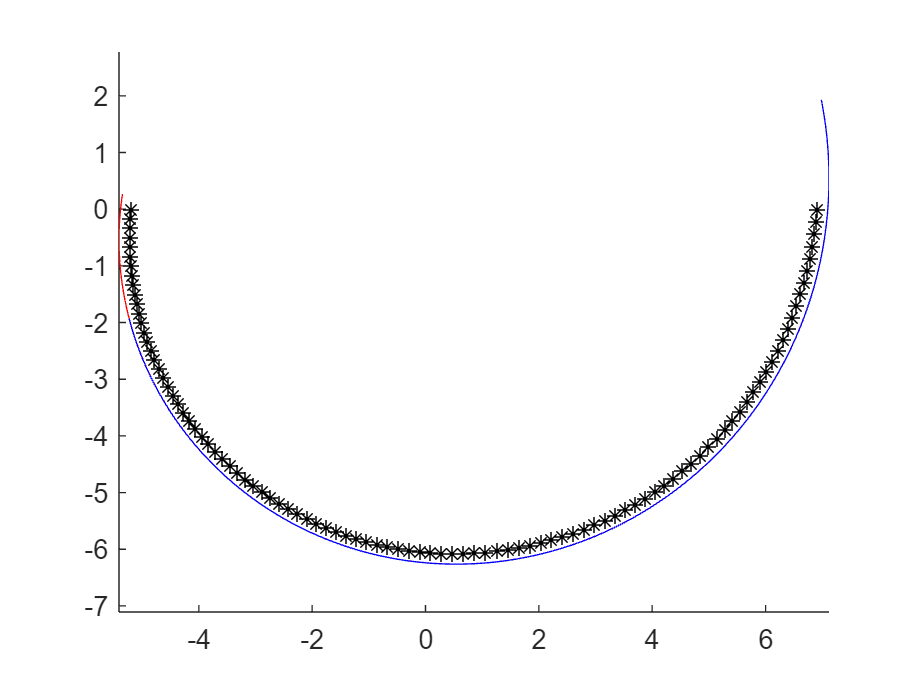

figure;
hold on;
thetas = linspace(3*pi, 4*pi, 100)';
akimid = 0.55 * [thetas.*cos(thetas), thetas.*sin(thetas)];
dingdian = zeros(200, 2);
for i = 1:100
    dingdian(i*2-1:i*2, :) = my_test(1.65, akimid(i,:), 0.55);
end

plot(akimid(:,1), akimid(:,2), '*k');
plot(dingdian(1:2:199,1), dingdian(1:2:199,2), '-r');
plot(dingdian(2:2:200,1), dingdian(2:2:200,2), '-b');
axis equal;